# Simulation

## Notes

This is a very simple set of exercises designed to provide some familiarity with random number generation

## Setup

Clear and reset the workspace and load required data

% Clean up everything
clear all
close all
clc
% Reset rng to make runs the same
rng('default')

## Simulate standard normal random variables

`randn` is the main function to simulate normal random variables.

x = randn(100,1);

## Simulate random variables with mean and variance

To get a particular mean and variance, multiple by the standard deviation and add the mean. Alternatively you can use `normrnd` which takes the mean and standard deviation as parameters. 

y = .08 + 0.2 * randn(100,1);
y2 = normrnd(0.08, 0.2, 100, 1);

## Simulate Students t random variables

`trnd` can be used to simulate Student's t random variables.

z = trnd(8,100,1);

## Simulate Students t random variables with mean and variance

`trnd` generates Student's t random variables. The variance of a Student's t with v degrees of freedom is v/(v-2) and so it is necessary to standardize them to have unit variance. 

v = 8;
w = trnd(v,10000,1);
w = w/sqrt(v/(v-2));
w = 0.08 + 0.20 * w;
disp('mean')

mean


mean(w)

ans = 0.0789

disp('std')

std


std(w)

ans = 0.2001

## Simulate identical sets random variables

Pseudo random numbers are very long, but ultimately deterministic, sequences.  Since the sequence is deterministic, it is possible to reset to the same condition which will produce the same values. Here the generator is reset using the command `rng` to first get the stats and then calling with the saved state to reset the random number generator to the same point. 

state = rng;
u1 = randn(100,1);
rng(state)
u2 = randn(100,1);
max(abs(u1-u2))

ans = 0

## Simulate Students t using only randn

Since Student's t random variables are defined as a normal divided by the square root of a an independent, standardized chi square and a chi square is just the sum of independent normal random variables squared, it is easy to construct these from only standard normals. 

n = 10000;

n = 10000

z2 = randn(n,1);
v = 8;
c = sum(randn(n,v).^2,2);
z2 = z2./sqrt(c/v);

## Verify similarity to Student T random variables

These should be close to the 45 degree line when plotted against Student T 8 random variables. The extremes will be noisier than the center.

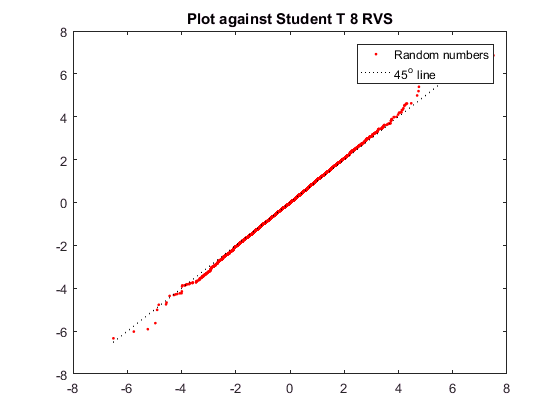

clf;
z3 = trnd(8,n, 1);
diag_line = linspace(min(min([z2,z3])),max(max([z2,z3])));
plot(sort(z2), sort(z3), 'r.', diag_line, diag_line, 'k:')
hold on
legend('Random numbers','45^o line')
title('Plot against Student T 8 RVS')